# RoadRunner - Path and vehicle speed tracking by cosimulation with Simulink (utilizing 14 degrees of freedom model of Vehicle Dynamics Blockset)

## Clean up variables and RoadRunner

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear; 

## Launch RoadRunner from MATLAB

rrApp = roadrunner();

% Copy required scenario and behavior files.
rrProjectPath = rrApp.status.Project.Filename;
copyfile("pathFollowingUtil/TrajectoryFollowBehavior14DoF.rrbehavior.rrmeta",fullfile(rrProjectPath,"Assets/Behaviors/"));
copyfile("pathFollowingUtil/slopeTest14DoF.rrscene", fullfile(rrProjectPath, "Scenes/"));
copyfile("pathFollowingUtil/slopeTest14DoF.rrscenario", fullfile(rrProjectPath, "Scenarios/"));

behaviorName = "TrajectoryFollowBehavior14DoF.rrbehavior";
% Start the scenario. Scenes are linked to the scenario, so they will open automatically.
rrApp.openScenario("slopeTest14DoF");
rrApp.setScenarioVariable("EgoVehicleBehavior", "<PROJECT>/Assets/Behaviors/" + behaviorName); %Set behavior file

rrSim = rrApp.createSimulation();

Connection status: 1
Connected to RoadRunner Scenario server on localhost:57331, with client id {d9c39ca7-7197-4058-91b2-14db835452e3}


rrSim.set("PacerStatus", "Off");
rrSim.set("MaxSimulationTime", 14);
set(rrSim,"Logging","on");

% Define a bus object to obtain RoadRunner information in Simulink.
% To support Reader and Writer blocks, some bus objects must be loaded.
load(fullfile(matlabroot,'toolbox','driving','drivingdata','rrScenarioSimTypes.mat'));

addpath("pathFollowingUtil");
helperSLTrajectoryFollowerWithRRScenarioSetup(); %Set vehicle dynamics parameters and control parameters.
% % Open Simulink model.
model_name = 'TrajectoryFollowVehicleWith14DoF.slx';
open_system(model_name);


% Align RoadRunner and Simulink execution step sizes.
timeStep = 0.01;
RRtimeStep = 0.1;
rrSim.set("StepSize", RRtimeStep); 

## Move the vehicle along the scenario trajectory

useDynamicsStanley = false; %Simulink model that moves according to the scenario trajectory.
vehicleVariant = "3DOF";

% Get vehicle initial values from RoadRunner and set them to the vehicle model.
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName);
% Start simulation
set(rrSim,"SimulationCommand","Start");
% Wait until RoadRunner Scenario simulation is finished.
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end

% Get log
rrLog = get(rrSim,"SimulationLog");

% Get vehicle speed
velocityAgent1 = get(rrLog,'Velocity','ActorID',1); % Get speed of Actor1
time1 = [velocityAgent1.Time];% Get time of Actor1

% Get vehicle movement
poseActor1 = rrLog.get('Pose','ActorID',1);
positionActor1_x = arrayfun(@(x) x.Pose(1,4),poseActor1);
positionActor1_y = arrayfun(@(x) x.Pose(2,4),poseActor1);

rotationActor1_eulZYX = cell2mat(arrayfun(@(x) tform2eul(x.Pose, "ZYX")', poseActor1, 'UniformOutput', false))';
rotationActor1_pitch = rad2deg(rotationActor1_eulZYX(:, 3)); 

## Bycycle model for vehicle dynamics, control by StanleyControl

useDynamicsStanley = true; %Simulink model that moves according to the scenario trajectory.
vehicleVariant = "3DOF";

% Get vehicle initial values from RoadRunner and set them to the vehicle model.
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName);
% Start simulation
set(rrSim,"SimulationCommand","Start");
% Wait until RoadRunner Scenario simulation is finished.
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end
% Get log
rrLog = get(rrSim,"SimulationLog");

% Get vehicle speed
velocityAgent2 = get(rrLog,'Velocity','ActorID',1); % Get speed of Actor1
time2 = [velocityAgent2.Time];% Get time of Actor1

% Get vehicle movement
poseActor2 = rrLog.get('Pose','ActorID',1);
positionActor2_x = arrayfun(@(x) x.Pose(1,4),poseActor2);
positionActor2_y = arrayfun(@(x) x.Pose(2,4),poseActor2);

rotationActor2_eulZYX = cell2mat(arrayfun(@(x) tform2eul(x.Pose, "ZYX")', poseActor2, 'UniformOutput', false))';
rotationActor2_pitch = rad2deg(rotationActor2_eulZYX(:, 3)); 

## Full vehicle model (14DoF) for vehicle dynamics, control by StanleyControl

If execution or build fails, please see the last section "For those who get execution/build errors." 

## 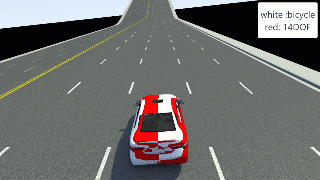

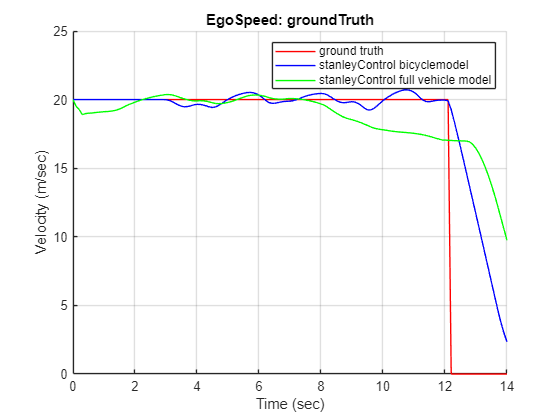

useDynamicsStanley = true; %Simulink model that moves according to the scenario trajectory.
vehicleVariant = "14DOF";

% Get vehicle initial values from RoadRunner and set them to the vehicle model.
helperSLTrajectoryFollowerWithRRScenarioSetup("rrAppObj", rrApp,...
    "scenarioSimulationObj", rrSim, "behaviorName", behaviorName);

% Load the terrain map created in advance
load("gridMap_groundHeight_RT.mat");%Output RoadRunner scene as a mesh file such as stl or fbx and convert to 2D height map to obtain
hegihtMap = "2DMap"; %Mode to use terrain map prepared in advance.
debug_engine3D = false;%If set to true, additional display will be provided by Unreal Engine.

% Set Unreal Engine scene to Empty.
load_system("sim3d_visualization");
Sim3DConfigPath = "sim3d_visualization/Simulation3DTerrain";
set_param(Sim3DConfigPath, "SourceFile", "");

% Start simulation
set(rrSim,"SimulationCommand","Start");
% Wait until RoadRunner Scenario simulation is finished.
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(1);
end
% Get log
rrLog = get(rrSim,"SimulationLog");

% Get vehicle speed
velocityAgent3 = get(rrLog,'Velocity','ActorID',1); % Get speed of Actor1
time3 = [velocityAgent3.Time];% Get time of Actor1

% Get vehicle movement
poseActor3 = rrLog.get('Pose','ActorID',1);
positionActor3_x = arrayfun(@(x) x.Pose(1,4),poseActor3);
positionActor3_y = arrayfun(@(x) x.Pose(2,4),poseActor3);

rotationActor3_eulZYX = cell2mat(arrayfun(@(x) tform2eul(x.Pose, "ZYX")', poseActor3, 'UniformOutput', false))';
rotationActor3_pitch = rad2deg(rotationActor3_eulZYX(:, 3));

## Comparison plot

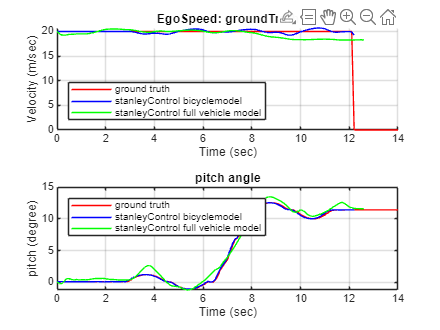

figure; tiledlayout(2, 1); nexttile;
helperPlotVelocity(time1, velocityAgent1, time2, velocityAgent2, time3, velocityAgent3);
title("EgoSpeed: groundTruth");
% Visualize vehicle pitch (road slope) as a function of vehicle speed reduction.
nexttile;
plot(time1, rotationActor1_pitch, "r"); hold on;
plot(time2, rotationActor2_pitch, "b");
plot(time3, rotationActor3_pitch, "g");
grid on;
ylabel("pitch (degree)")
xlabel("Time (sec)")
legend(["ground truth","stanleyControl bicyclemodel", "stanleyControl full vehicle model"], 'Location','northwest');
title("pitch angle");

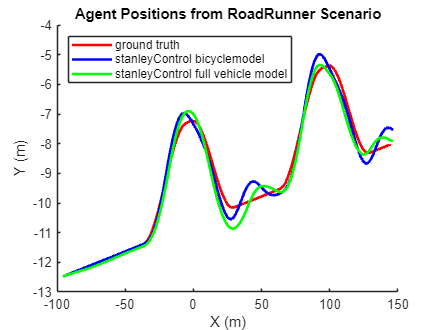


helperPlotTrajectory(positionActor1_x, positionActor1_y, positionActor2_x, positionActor2_y,...
    positionActor3_x, positionActor3_y); 

## "For those who get execution/build errors"

Possible errors and solutions are listed below. 

・ ** Error 1: RoadRunner Scenario and Simulink time out because the build is too long **

When RoadRunner and Simulink are cosimulating, if the execution time of one step is long, it will time out. The first step takes time to build the vehicle model, so it may time out. 

You can increase the timeout setting in `SimulationConfiguration.xml`. After setting it to a value equal to or greater than the build time, restart MATLAB and RoadRunner. 

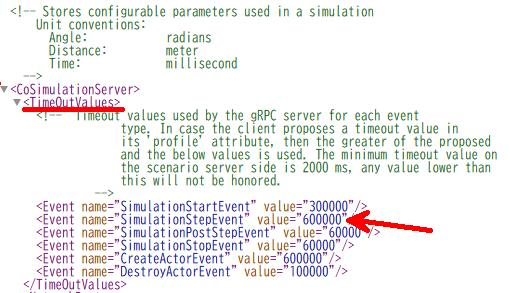

`SimulationConfiguration.xml can be found from the following path in each OS`

- Windows: `C:\Users\``username``\AppData\Roaming\MathWorks\RoadRunner\``R20NNa``\Scenario\Config\SimulationConfiguration.xml`

- `Ubuntu:` `~/.local/share/MathWorks/RoadRunner/``R20NNa``/Scenario/Config/SimulationConfiguration.xml`

・Error 2: A build error occurs with the compiler settings being used. 

To shorten the execution time, the vehicle model is set to Accelerator and built. If the build fails, try changing the Simulation mode to Normal as shown below. 

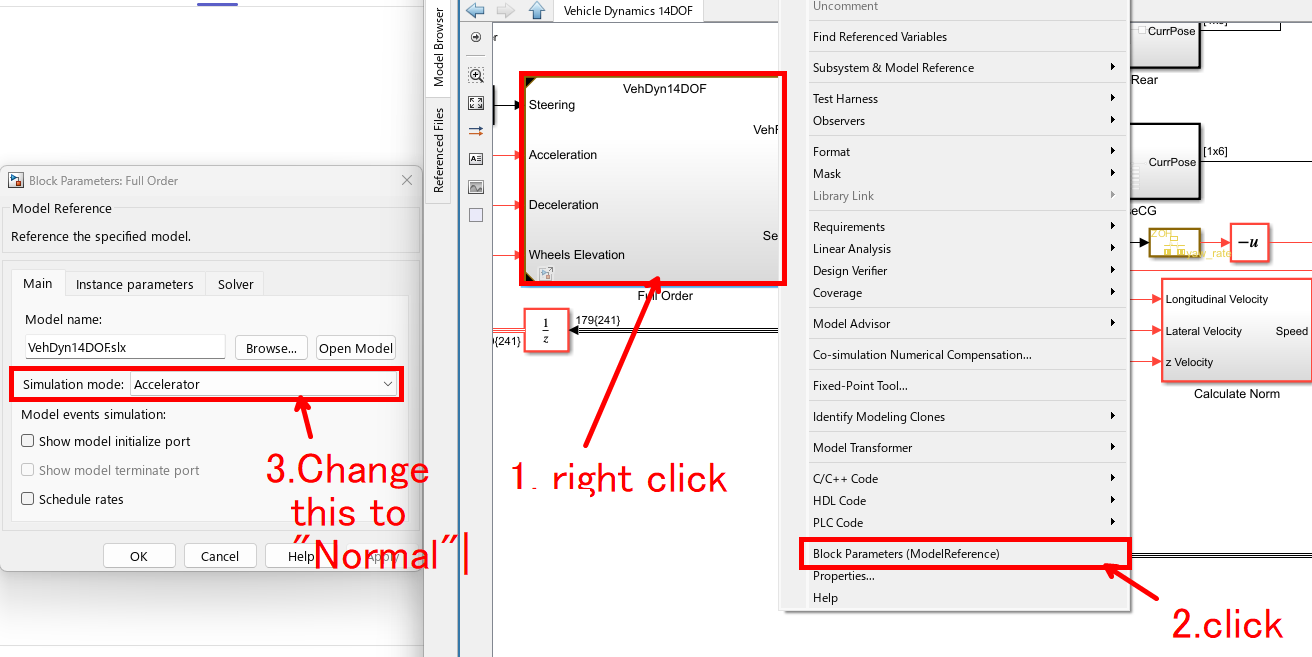

## Helper function

function helperPlotVelocity(time1, velocityAgent1, time2, velocityAgent2, time3, velocityAgent3)
    velMagAgent1 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent1);
    velMagAgent2 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent2);
    velMagAgent3 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent3);


    % Plot the agent velocities with respect to simulation time using the plot function. Label the graph and the x and y axes.
    hold on
    plot(time1,velMagAgent1,"r")
    plot(time2,velMagAgent2,"b")
    plot(time3,velMagAgent3,"g")
    grid on
    title("Agent Velocities from RoadRunner Scenario")
    ylabel("Velocity (m/sec)")
    xlabel("Time (sec)")
    legend(["ground truth","stanleyControl bicyclemodel", "stanleyControl full vehicle model"], 'Location','southwest');
end
function helperPlotTrajectory(positionActor1_x, positionActor1_y, positionActor2_x, positionActor2_y, positionActor3_x, positionActor3_y)
    % hdMap = getMap(rrSim);
    % lanes = hdMap.map.lanes;
    % Loop through each of the lane specifications using a for loop and plot the lane coordinates.
    
    figure
    hold on
    % for i = 1:numel(lanes)
    %     control_points = lanes(i).geometry.values;
    %     x_coordinates = arrayfun(@(cp) cp.x,control_points);
    %     y_coordinates = arrayfun(@(cp) cp.y,control_points);
    %     plot(x_coordinates, y_coordinates, 'black');
    % end
    plot(positionActor1_x,positionActor1_y,"r","LineWidth",2);
    hold on;
    plot(positionActor2_x,positionActor2_y,"b","LineWidth",2);
    plot(positionActor3_x,positionActor3_y,"g","LineWidth",2);
    legend(["ground truth","stanleyControl bicyclemodel", "stanleyControl full vehicle model"], 'Location','northwest');
    title("Agent Positions from RoadRunner Scenario");
    ylabel("Y (m)");
    xlabel("X (m)");
end